# get a glance of the data

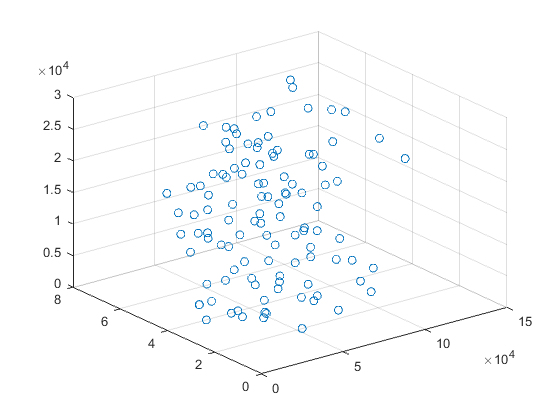


scatter3(exp3.x1,exp3.x2,exp3.y)

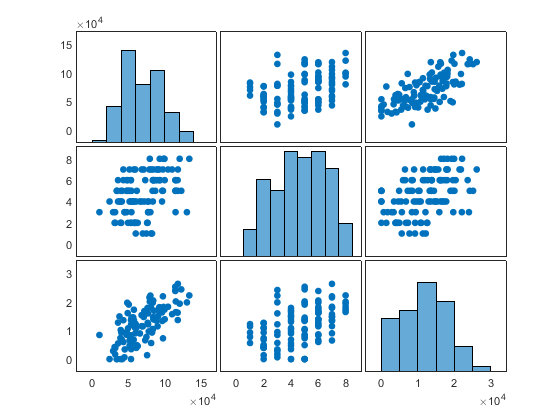

plotmatrix(exp3.Variables)

## fit a line

[model,gof,output]=fit([exp3.x1,exp3.x2],exp3.y,"poly23")


     Linear model Poly13:
     model(x,y) = p00 + p10*x + p01*y + p11*x*y + p02*y^2 + p12*x*y^2 + p03*y^3
     Coefficients (with 95% confidence bounds):
       p00 =       7.204  (-1.836e+04, 1.838e+04)
       p10 =     0.06234  (-0.1833, 0.308)
       p01 =       682.5  (-8876, 1.024e+04)
       p11 =     0.05101  (-0.05648, 0.1585)
       p02 =      -426.9  (-2196, 1342)
       p12 =   -0.006145  (-0.01731, 0.005017)
       p03 =       64.11  (-72.4, 200.6)



gof = 包含以下字段的 struct :
           sse: 2.0532e+09
       rsquare: 0.5477
           dfe: 102
    adjrsquare: 0.5211
          rmse: 4.4865e+03


output = 包含以下字段的 struct :
        numobs: 109
      numparam: 7
     residuals: [109×1 double]
      Jacobian: [109×7 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


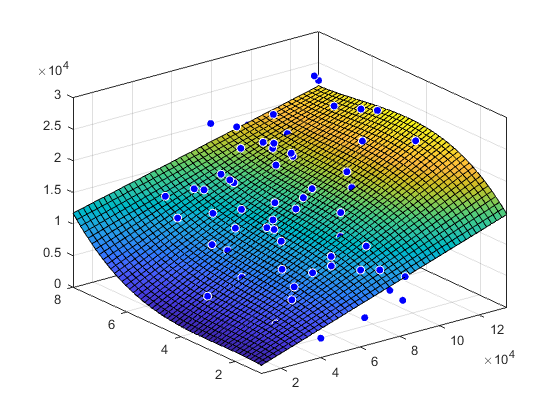

plot(model,[exp3.x1,exp3.x2],exp3.y)

model([exp3.x1(25) exp3.x2(25)])

ans = 1.4938e+04

exp3.y(25)

ans = 1.9640e+04

## let's look at the result

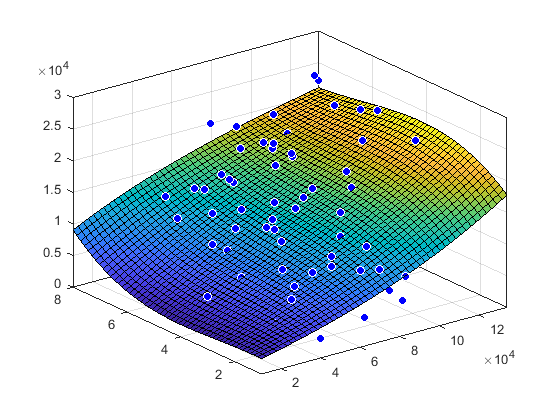

hold off

% this shows the goodness of the fit
gof

gof = 包含以下字段的 struct :
           sse: 2.0505e+09
       rsquare: 0.5483
           dfe: 99
    adjrsquare: 0.5073
          rmse: 4.5510e+03


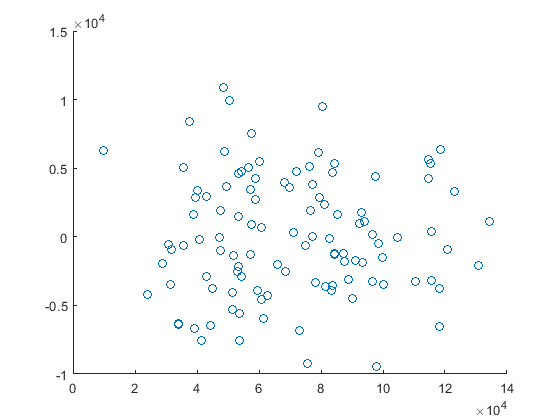

% let's plot the residuals
scatter(exp3.x1,output.residuals)

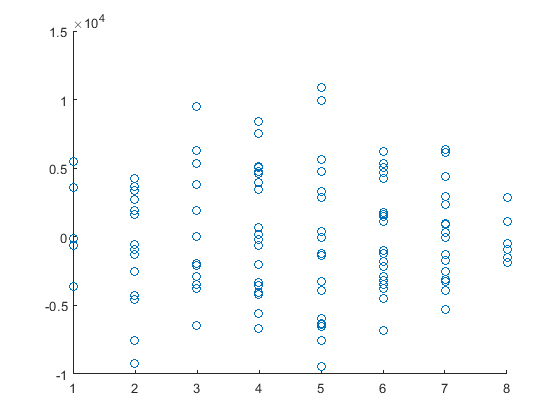

scatter(exp3.x2,output.residuals)

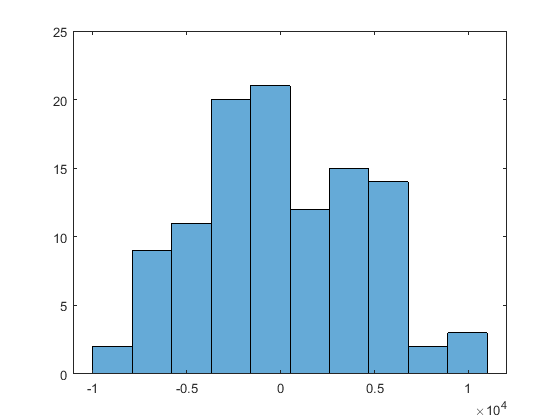

错误使用 plot
需要字符串标量或字符向量形式的参数名称。

出错 sfit/plot>iParseInputs (line 235)
p.parse( parameterValuePairs{:} );

出错 sfit/plot (line 48)
[XY, Z, in, out, style, level, hParent] = iParseInputs( obj, varargin{:} );

histogram(output.residuals,10)

model


     Linear model Poly33:
     model(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p30*x^3 
                    + p21*x^2*y + p12*x*y^2 + p03*y^3
     Coefficients (with 95% confidence bounds):
       p00 =        1787  (-1.948e+04, 2.306e+04)
       p10 =     0.01203  (-0.5194, 0.5435)
       p01 =       280.2  (-1.013e+04, 1.069e+04)
       p20 =   3.106e-07  (-7.214e-06, 7.836e-06)
       p11 =     0.05866  (-0.06753, 0.1849)
       p02 =      -381.7  (-2239, 1476)
       p30 =   1.633e-12  (-3.796e-11, 4.122e-11)
       p21 =  -1.289e-07  (-1.029e-06, 7.713e-07)
       p12 =   -0.004886  (-0.01972, 0.009949)
       p03 =        54.4  (-100.7, 209.5)



gof

gof = 包含以下字段的 struct :
           sse: 2.0505e+09
       rsquare: 0.5483
           dfe: 99
    adjrsquare: 0.5073
          rmse: 4.5510e+03
